Initialization

clc
clear
warning off
syms ln lo x f 

Inputs from the user

f(x) = input('enter the function = ') %test function = x.^2 + 2*x

$$f(x) = x^{2}+2\,x$$

a = input('enter the lower limit of interval = ') %test value = -3 

a = -3

b = input('enter the upper limit of interval = ') %test value =  4 

b = 4

N = input('enter the percentage of error needed = ') %test value = 5 

N = 1.0000e-05

n = input('enter the fibonaaci number till the calculation is needed = ') %test value = 20 

n = 20

r = a:0.1:b;
ezplot(f,[r])
hold on

Measure of efficiency

ln/lo <= (2*N)/100;

calculating the fibonacci value required for given user inputs

Fn = double(100/(2*N));
fprintf('The Fibonacci value should be greater than  : %d \n',Fn)

The Fibonacci value should be greater than  : 5000000 


Fibonnaci function


for i = 1:n
    if i==1 || i==2
        fo = 1;
        fn = 1;
        F(i)=1;
   continue;
    end

        F(i) = fo+fn;
        fo = fn;
        fn = F(i);
   
    if(Fn>= F(i))
        finali = i;
    end 
end

Total number of experiments needed for the given user inputs

n = finali;
fprintf('The total number of experiments are : %d \n',n)

The total number of experiments are : 20 


Initial interval of uncertainity

lo = b-a; 
fprintf('The initial interval of uncertainity is : %d \n',lo)

The initial interval of uncertainity is : 7 


Looping to get L* values, reduction lengths, experimenrts and the functional values of experiments

for i = 0:n-2
    Lstr(i+2) = (fibonacci(n-(i+1))/fibonacci(n+1)) * lo;

    fprintf('The reduction length [L(%d)*] for %g iteration in the interval of uncertainity is : %g \n',i+2,i+1,Lstr(1,i+2))
    x1 = a + Lstr(i+2);

    fprintf('The  x(%g) experiment is at : %18.15f \n',i+1,x1)
    
    x2 = b - Lstr(i+2);
    fprintf('The  x(%g) experiment is at : %18.15f \n',i+2,x2)
      
    plot(x1,f(x2),'.','MarkerSize',10)

    fx1 = double(f(x1));
    fprintf('The  value of function at x(%g)  : %18.15f \n',i+1,fx1)
    fx2 = double(f(x2));
    fprintf('The  value of function at x(%g)  : %18.15f \n',i+2,fx2)
    

Condition to check which function is greater and updating the new interval of uncertainity 

     if(double(f(x1)) < double(f(x2)))
        a;                 
        b = x2;
        fprintf('The  %d interval of uncertainity is  :  %18.15f, %18.15f \n',i+1,a,b)
    end

    if(double(f(x1)) > double(f(x2)))
        a = x1;
        b;               
        fprintf('The  %d interval of uncertainity is  : %18.15f, %18.15f \n',i+1,a,b)
    end
    if(double(f(x1)) == double(f(x2)))
        disp('minima has been reached')
    end
  fprintf('\n')

Update the final results  

end

The reduction length [L(2)*] for 1 iteration in the interval of uncertainity is : 2.67376 


The  x(1) experiment is at : -0.326237895121506 


The  x(2) experiment is at :  1.326237895121506 


The  value of function at x(1)  : -0.546044626029701 


The  value of function at x(2)  :  4.411382744699333 


The  1 interval of uncertainity is  :  -3.000000000000000,  1.326237895121506 


The reduction length [L(3)*] for 2 iteration in the interval of uncertainity is : 1.65248 


The  x(2) experiment is at : -1.347524209756989 


The  x(3) experiment is at : -0.326237895121505 


The  value of function at x(2)  : -0.879226923632780 


The  value of function at x(3)  : -0.546044626029701 


The  2 interval of uncertainity is  :  -3.000000000000000, -0.326237895121505 


The reduction length [L(4)*] for 3 iteration in the interval of uncertainity is : 1.02129 


The  x(3) experiment is at : -1.978713685364517 


The  x(4) experiment is at : -1.347524209756989 


The  value of function at x(3)  : -0.042119522080206 


The  value of function at x(4)  : -0.879226923632780 


The  3 interval of uncertainity is  : -1.978713685364517, -0.326237895121505 


The reduction length [L(5)*] for 4 iteration in the interval of uncertainity is : 0.631189 


The  x(4) experiment is at : -1.347524209756989 


The  x(5) experiment is at : -0.957427370729033 


The  value of function at x(4)  : -0.879226923632780 


The  value of function at x(5)  : -0.998187571236957 


The  4 interval of uncertainity is  : -1.347524209756989, -0.326237895121505 


The reduction length [L(6)*] for 5 iteration in the interval of uncertainity is : 0.390097 


The  x(5) experiment is at : -0.957427370729033 


The  x(6) experiment is at : -0.716334734149461 


The  value of function at x(5)  : -0.998187571236957 


The  value of function at x(6)  : -0.919534016949943 


The  5 interval of uncertainity is  :  -1.347524209756989, -0.716334734149461 


The reduction length [L(7)*] for 6 iteration in the interval of uncertainity is : 0.241093 


The  x(6) experiment is at : -1.106431573177416 


The  x(7) experiment is at : -0.957427370729033 


The  value of function at x(6)  : -0.988672320230980 


The  value of function at x(7)  : -0.998187571236957 


The  6 interval of uncertainity is  : -1.106431573177416, -0.716334734149461 


The reduction length [L(8)*] for 7 iteration in the interval of uncertainity is : 0.149004 


The  x(7) experiment is at : -0.957427370729033 


The  x(8) experiment is at : -0.865338936597844 


The  value of function at x(7)  : -0.998187571236957 


The  value of function at x(8)  : -0.981866398003400 


The  7 interval of uncertainity is  :  -1.106431573177416, -0.865338936597844 


The reduction length [L(9)*] for 8 iteration in the interval of uncertainity is : 0.0920884 


The  x(8) experiment is at : -1.014343139046227 


The  x(9) experiment is at : -0.957427370729033 


The  value of function at x(8)  : -0.999794274362301 


The  value of function at x(9)  : -0.998187571236957 


The  8 interval of uncertainity is  :  -1.106431573177416, -0.957427370729033 


The reduction length [L(10)*] for 9 iteration in the interval of uncertainity is : 0.0569158 


The  x(9) experiment is at : -1.049515804860223 


The  x(10) experiment is at : -1.014343139046227 


The  value of function at x(9)  : -0.997548185069044 


The  value of function at x(10)  : -0.999794274362301 


The  9 interval of uncertainity is  : -1.049515804860223, -0.957427370729033 


The reduction length [L(11)*] for 10 iteration in the interval of uncertainity is : 0.0351727 


The  x(10) experiment is at : -1.014343139046227 


The  x(11) experiment is at : -0.992600036543029 


The  value of function at x(10)  : -0.999794274362301 


The  value of function at x(11)  : -0.999945240540835 


The  10 interval of uncertainity is  : -1.014343139046227, -0.957427370729033 


The reduction length [L(12)*] for 11 iteration in the interval of uncertainity is : 0.0217431 


The  x(11) experiment is at : -0.992600036543029 


The  x(12) experiment is at : -0.979170473232231 


The  value of function at x(11)  : -0.999945240540835 


The  value of function at x(12)  : -0.999566130814631 


The  11 interval of uncertainity is  :  -1.014343139046227, -0.979170473232231 


The reduction length [L(13)*] for 12 iteration in the interval of uncertainity is : 0.0134296 


The  x(12) experiment is at : -1.000913575735428 


The  x(13) experiment is at : -0.992600036543029 


The  value of function at x(12)  : -0.999999165379376 


The  value of function at x(13)  : -0.999945240540835 


The  12 interval of uncertainity is  :  -1.014343139046227, -0.992600036543029 


The reduction length [L(14)*] for 13 iteration in the interval of uncertainity is : 0.00831354 


The  x(13) experiment is at : -1.006029599853828 


The  x(14) experiment is at : -1.000913575735428 


The  value of function at x(13)  : -0.999963643925603 


The  value of function at x(14)  : -0.999999165379376 


The  13 interval of uncertainity is  : -1.006029599853828, -0.992600036543029 


The reduction length [L(15)*] for 14 iteration in the interval of uncertainity is : 0.00511602 


The  x(14) experiment is at : -1.000913575735428 


The  x(15) experiment is at : -0.997716060661429 


The  value of function at x(14)  : -0.999999165379376 


The  value of function at x(15)  : -0.999994783621098 


The  14 interval of uncertainity is  :  -1.006029599853828, -0.997716060661429 


The reduction length [L(16)*] for 15 iteration in the interval of uncertainity is : 0.00319752 


The  x(15) experiment is at : -1.002832084779828 


The  x(16) experiment is at : -1.000913575735428 


The  value of function at x(15)  : -0.999991979295800 


The  value of function at x(16)  : -0.999999165379376 


The  15 interval of uncertainity is  : -1.002832084779828, -0.997716060661429 


The reduction length [L(17)*] for 16 iteration in the interval of uncertainity is : 0.00191851 


The  x(16) experiment is at : -1.000913575735428 


The  x(17) experiment is at : -0.999634569705829 


The  value of function at x(16)  : -0.999999165379376 


The  value of function at x(17)  : -0.999999866460700 


The  16 interval of uncertainity is  : -1.000913575735428, -0.997716060661429 


The reduction length [L(18)*] for 17 iteration in the interval of uncertainity is : 0.00127901 


The  x(17) experiment is at : -0.999634569705829 


The  x(18) experiment is at : -0.998995066691029 


The  value of function at x(17)  : -0.999999866460700 


The  value of function at x(18)  : -0.999998990109044 


The  17 interval of uncertainity is  :  -1.000913575735428, -0.998995066691029 


The reduction length [L(19)*] for 18 iteration in the interval of uncertainity is : 0.000639503 


The  x(18) experiment is at : -1.000274072720629 


The  x(19) experiment is at : -0.999634569705829 


The  value of function at x(18)  : -0.999999924884144 


The  value of function at x(19)  : -0.999999866460700 


The  18 interval of uncertainity is  :  -1.000913575735428, -0.999634569705829 


The reduction length [L(20)*] for 19 iteration in the interval of uncertainity is : 0.000639503 


The  x(19) experiment is at : -1.000274072720629 


The  x(20) experiment is at : -1.000274072720629 


The  value of function at x(19)  : -0.999999924884144 


The  value of function at x(20)  : -0.999999924884144 


minima has been reached


  lup = x1;       % one can also update x2, as x1 and x2 are preety close at minima 
    fup = (f(lup));

Final minima and its functional value

   fprintf('The final minima point is  : %18.15f \n',lup)

The final minima point is  : -1.000274072720629 


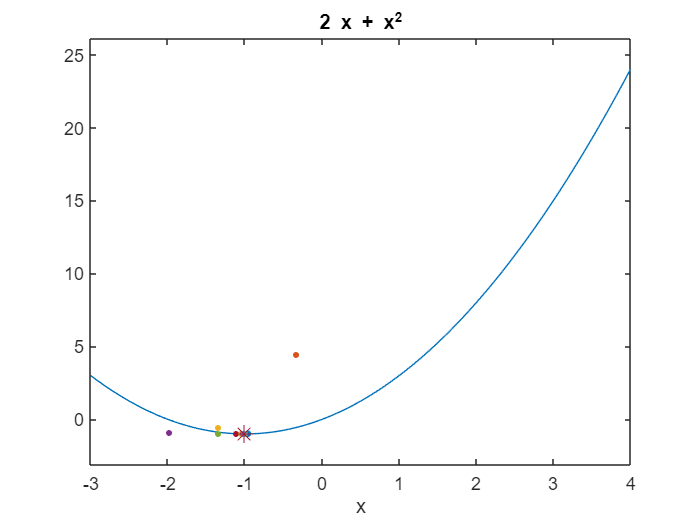

   plot(x1,f(x2),'-*','MarkerSize',10)
   hold off

   fprintf('The function value at minima point is  : %18.15f \n',fup)

The function value at minima point is  : -0.999999924884144 
